# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

O método de resíduos ponderados consiste em:

- achar um conjunto de funções que satisfaçam as condições de contorno do problema (PVC);

- avaliar uma C. Linear dessas funções de forma, buscando que o resíduo da solução com funções pesos associada a cada direção seja nulo;

- A diferentes tipos de funções de forma que podem ser utilizadas, nesse código, utilizou-se: Método de galerkins

Número de graus de liberdade:

m=4;

Tamanho do domínio trabalhado:

left=0;
right=1;

Vetor com os coeficientes de cada função de forma (simbólico):

C = sym('c',[1 m]);

Vetor com as funções da série de fourier generalizada (funções de forma)

syms x
N = sym('N',[1 m]);
for i=1:m
    N(1,i)=sin((2*i-1)*pi*x/2); %funções que usa-se como base do sistema
end

Solução genérica (tentativa inicial)

w_0=x;      %w_0 será a função para satisfazer os termos do contorno
y=w_0+dot(N,C);

Equações do Resíduo aplicada na Eq diferencial:

- Derivadas da solução genérica:

y1=diff(y,x);       
y2=diff(y1,x);       
y3=diff(y2,x); 

$$y\_sol = x-\frac{32\,\sin\left(\frac{\pi \,\bar{x}}{2}\right)\,\left(\pi -4\right)}{\pi^{3}\,\left(\pi^{2}-4\right)}+\frac{32\,\sin\left(\frac{3\,\pi \,\bar{x}}{2}\right)\,\left(3\,\pi +4\right)}{27\,\pi^{3}\,\left(9\,\pi^{2}-4\right)}-\frac{32\,\sin\left(\frac{5\,\pi \,\bar{x}}{2}\right)\,\left(5\,\pi -4\right)}{125\,\pi^{3}\,\left(25\,\pi^{2}-4\right)}+\frac{32\,\sin\left(\frac{7\,\pi \,\bar{x}}{2}\right)\,\left(7\,\pi +4\right)}{343\,\pi^{3}\,\left(49\,\pi^{2}-4\right)}$$

$$simplifiedExpr = x-\frac{32\,\sin\left(\frac{\pi \,\bar{x}}{2}\right)\,\left(\pi -4\right)}{\pi^{3}\,\left(\pi^{2}-4\right)}+\frac{32\,\sin\left(\frac{3\,\pi \,\bar{x}}{2}\right)\,\left(3\,\pi +4\right)}{27\,\pi^{3}\,\left(9\,\pi^{2}-4\right)}-\frac{32\,\sin\left(\frac{5\,\pi \,\bar{x}}{2}\right)\,\left(5\,\pi -4\right)}{125\,\pi^{3}\,\left(25\,\pi^{2}-4\right)}+\frac{32\,\sin\left(\frac{7\,\pi \,\bar{x}}{2}\right)\,\left(7\,\pi +4\right)}{343\,\pi^{3}\,\left(49\,\pi^{2}-4\right)}$$

- Função resíduo:

R=y2+y-x^2;

- Solução pelo método de galerkins:

E=int(R*N,x,[left right]);
sol_c=solve(E);

- Transformar struct em célula, para avaliar a função solução

a=struct2cell(sol_c)';
y_sol=subs(y,C,a);

Plot dos gráficos:

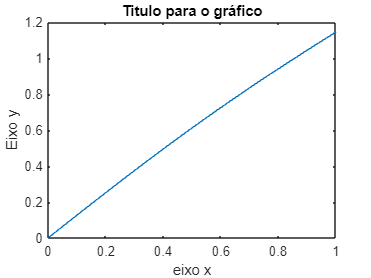

xplot=linspace(left,right,100);
yp=subs(y_sol,x,xplot);
plot(xplot,yp);
title('Titulo para o gráfico')
xlabel('eixo x');
ylabel('Eixo y');